# Perceptron y Adaline sobre cada version del dato

Se toman las cinco tablas que dejaron R1 y R2, se parte 70-30 y se entrena el perceptron y el Adaline sobre cada una.

clear; close all; clc
pasos = {'T0_crudo','T1_outliers','T2_balanceado','T3_estandarizado','T4_normalizado'};

## Iris: A) setosa vs resto B) versicolor vs virginica

load iris_pasos.mat
vars = {'largo_sepalo','ancho_sepalo','largo_petalo','ancho_petalo'};
problemas = {'A: setosa vs resto', 'B: versicolor vs virginica'};
R_iris = table();
for pr = 1:2
    for k = 1:5
        T = eval(pasos{k});
        if pr == 1
            X = T{:,vars};  y = double(T.clase == 'setosa');
        else
            m = T.clase ~= 'setosa';
            X = T{m,vars};  y = double(T.clase(m) == 'versicolor');
        end
        [acc_p, ep_p, acc_a, ep_a] = entrenar_los_dos(X, y);
        R_iris = [R_iris; table(problemas(pr), pasos(k), ep_p, acc_p, ep_a, acc_a, ...
                  'VariableNames', {'Problema','Paso','Epocas_perceptron','Exact_perceptron','Epocas_adaline','Exact_adaline'})];
    end
end
R_iris

R_iris = 10×6 table
               Problema                       Paso            Epocas_perceptron    Exact_perceptron    Epocas_adaline    Exact_adaline
    ______________________________    ____________________    _________________    ________________    ______________    _____________

    {'A: setosa vs resto'        }    {'T0_crudo'        }             2                   100              372                100    
    {'A: setosa vs resto'        }    {'T1_outliers'     }             2                   100              346                100    
    {'A: setosa vs resto'        }    {'T2_balanceado'   }             2                   100              346                100    
    {'A: setosa vs resto'        }    {'T3_estandarizado'}             2                   100               40                100    
    {'A: setosa vs resto'        }    {'T4_normalizado'  }             4                   100              500                100    
    {'B: versicolor vs virginica'}

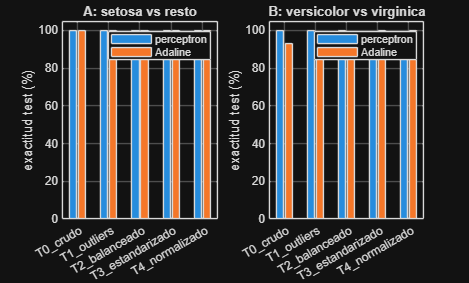


figure
for pr = 1:2
    subplot(1,2,pr)
    m = strcmp(R_iris.Problema, problemas{pr});
    bar([R_iris.Exact_perceptron(m) R_iris.Exact_adaline(m)]); ylim([0 105]); grid on
    set(gca, 'XTickLabel', pasos, 'TickLabelInterpreter', 'none')
    ylabel('exactitud test (%)'); title(problemas{pr}); legend('perceptron','Adaline')
end

## Banknote

load banknote_pasos.mat
vars = {'varianza','asimetria','curtosis','entropia'};
R_bank = table();
for k = 1:5
    T = eval(pasos{k});
    X = T{:,vars};  y = double(T.clase == 'falso');
    [acc_p, ep_p, acc_a, ep_a, ec_a] = entrenar_los_dos(X, y);
    R_bank = [R_bank; table(pasos(k), height(T), ep_p, acc_p, ep_a, ec_a, acc_a, ...
              'VariableNames', {'Paso','Filas','Epocas_perceptron','Exact_perceptron','Epocas_adaline','EC_final_adaline','Exact_adaline'})];
end
R_bank

R_bank = 5×7 table
            Paso            Filas    Epocas_perceptron    Exact_perceptron    Epocas_adaline    EC_final_adaline    Exact_adaline
    ____________________    _____    _________________    ________________    ______________    ________________    _____________

    {'T0_crudo'        }    1372            200                99.029                6               46.772             97.33    
    {'T1_outliers'     }    1372            200                98.786                6               32.089             97.33    
    {'T2_balanceado'   }    1220             43                98.907                6               29.365            95.902    
    {'T3_estandarizado'}    1220             23                 99.18                7               13.373            97.541    
    {'T4_normalizado'  }    1220             42                98.907              161               13.068            97.268    


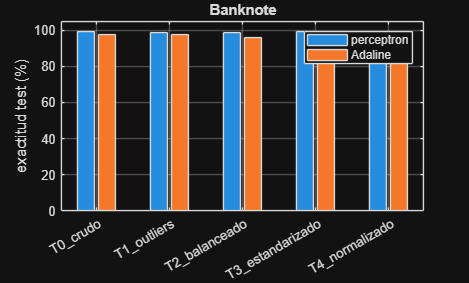


figure
bar([R_bank.Exact_perceptron R_bank.Exact_adaline]); ylim([0 105]); grid on
set(gca, 'XTickLabel', pasos, 'TickLabelInterpreter', 'none')
ylabel('exactitud test (%)'); title('Banknote'); legend('perceptron','Adaline')

## Parte 70-30, entrena los dos y devuelve exactitud en test

function [acc_p, ep_p, acc_a, ep_a, ec_a] = entrenar_los_dos(X, y)
    rng(2021)
    ind = randperm(numel(y));
    n_tr = round(0.7 * numel(y));
    tr = ind(1:n_tr);  te = ind(n_tr+1:end);

    d = 2*y - 1;                                   % perceptron con salida en {-1,1}
    [w, b, ep_p] = perceptron(X(tr,:), d(tr), 3, 0.1, 0, [-1 1], 200, 1);
    acc_p = 100*mean(predecir(X(te,:), w, b, 0, [-1 1]) == d(te));

    [w, b, ep_a, EC] = adaline(X(tr,:), y(tr), 0.01, 1e-3, 500, 1);   % Adaline con salida en {0,1}
    acc_a = 100*mean(predecir(X(te,:), w, b, 0.5, [0 1]) == y(te));
    ec_a = EC(end);
end